Quiz 4

syms x
f = matlabFunction(log10(x)./log10(5) + cos(x) + sqrt(x));

xx = [0.5 1 2 2.5 3 3.5]'

xx =     0.5000
    1.0000
    2.0000
    2.5000
    3.0000
    3.5000



yy = f(xx)

yy =     1.1540
    1.5403
    1.4287
    1.3493
    1.4247
    1.7128



test1 = f(2.4)

test1 = 1.3558


newton = polynewton(xx, yy);

newton_test1 = polyval(newton, 2.4)

newton_test1 = 1.3556

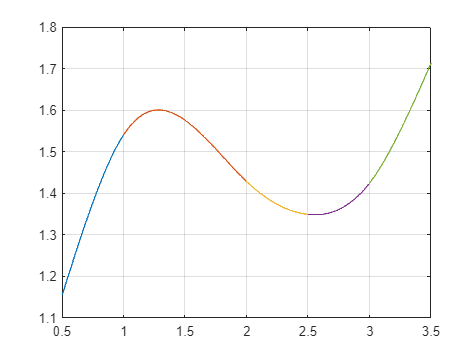

spline =    -0.6403         0    0.9326    1.1540
    0.3964   -0.9604    0.4524    1.5403
    0.0235    0.2288   -0.2791    1.4287
    0.2055    0.2640   -0.0327    1.3493
   -0.3815    0.5722    0.3854    1.4247



spline = splinenatural(xx',yy')


% se escoge x en la posición 3 y la tercera fila del spline por el
% intervalo [2, 2.5]
xx(3);
spline(3, :);
spline_test1 = spline(3, 1)*((2.4 - xx(3))^3) + spline(3,2)*((2.4 - xx(4))^2) + spline(3,3)*(2.4 - xx(3)) + spline(3,4)

spline_test1 = 1.3209


if (abs(test1 - newton_test1) < abs(test1 - spline_test1))
    op = 0
else
    op = 1
end

op = 0

function M = tabladif(x,y)
    n = length(x);
    M = zeros(n);
    M(1:n,1) = y;

    for k = 1:n-1
        delta_x = x(k+1:n)-x(1:n-k);
        delta_y = diff(y)./delta_x;
        M(1:n-k,k+1) = delta_y;
        y = delta_y;
    end
    
    M = [x M];
end

function p = polynewton(x, y)
    M = tabladif(x, y);
    n = length(x);
    b = M(1, 2:end);
    p = b(1);
    for k = 2:n
        p = [0 p] + b(k) * poly(x(1:k-1));
    end
end

function S=splinenatural(X,Y)
    N=length(X)-1;
    H=diff(X);
    E=diff(Y)./H;
    diagprinc=2*(H(1:N-1)+H(2:N));
    diagsupinf=H(2:N-1);
    g0=0; gn=0;
    A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b=6*diff(E');
    g=A\b';
    g = [g0 g' gn];

    for i=1:N
        S(i,1)=(g(i+1)-g(i))/(6*H(i));
        S(i,2)=g(i)/2;
        S(i,3)=E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4)=Y(i);
        xx=linspace(X(i),X(i+1),100);
        yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy);
        hold on
    end
    grid on
    hold off
end